addpath 'Exp Data'
clc
clear all;

# Term Project Report

## Modelling

### Determining System Parameters from Experimental Data

First, the experimental data is imported and the values of system constants $K_m, ~K_t, ~K_p, $ and $K_a$ are determined using various techniques.  The data is found in the "SS_speeds_voltages_data.xlsx" excel spreadsheet located in the "Exp Data" repository sub-folder. The parameters are defined as follows:


$$\begin{array}{rl}

K_m

&= ~\frac{ \omega_{ss}}{v_m} \\

K_t

&= ~\frac{v_t}{ \omega}\\

K_p

&= ~\frac{v_p}{ \theta_o}\\

K_a

&= ~\frac{v_m}{v_o}



\end{array}$$


$K_m$ is the motor speed constant (which is related to additional motor parameters below),  the tachometer constant is $K_t$, the potentiometer constant is$K_p$, and the inverting power amplifier constant is $K_a$. The variable $\omega_{ss}$ is the motor's steady state angular velocity reached when a step input voltage of $v_m$ is applied. The voltage $v_t$ is an output of the tachometer for any given instantanous motor angular velocity $\omega$. For the position constant, the voltage $v_p$ represents the potentiometer voltage reading given gear reduced ouput angle $\theta_o$. This output angle is related to the motor shaft angle through gear ratio $N$: 

$\theta_o = \frac{\theta_m}{N}$.

In addition to these parameters, the motor-with-gearbox open loop time constant $\tau_m$ must be determined from step response data provided. This, along with $K_m$ (also determined experimentally) will provide for almost all of the relationships that will be needed to model the motor within the system. Their equations are:


$$\tau_m ~=~ \frac{J_m}{K_{fm} + \frac{K_c}{R_a}K_b}$$


and 


$$K_m ~=~ \frac{ \frac{K_c}{R_a}}{K_{fm} + \frac{K_c}{R_a}K_b}$$


Where $K_{fm}$ is the motor's viscous damping coefficient, $R_a$ is its armature resistance, $K_c$ is its torque/current constant, $K_b$ is its back emf constant, and $J_m$ is the combined mass moment of inertia of the motor armature and the gearbox. One more experimental measurement is required - the ratio $ \frac{K_c}{R_a}$ can be ascertained from the static torque required to move the pendulum from equilibrium when it is at -90 degrees (horizontal). This static torque-voltage constant is found from: 


$$ \frac{K_c}{R_a} ~=~ \frac{MgL}{v_{m,0}}$$


where $M$is the mass of the pendulum bob, $g$ is the gravitational constant, and $L$ is the moment arm from the pendulum's point of rotation to the pendulum bob. 

%%Set up the Import Options and Import the Steady State Speed vs. Voltage Data

%This portion of code was generated automatically in MATLAB using the "Import Data" tool 
%and its "Generate Script" functionality. The file path for the readtable function call 
% has been modified to work with the file system scheme used in this report. Additionally, 
% the data originally output as an array is transfered into the struct "SS_w_v_dat". 

opts = spreadsheetImportOptions("NumVariables", 4);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A3:D13";

% Specify column names and types
opts.VariableNames = ["MotorSpeed", "Vo", "Vm", "VT"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Import the data
SSspeedsvoltagesdata = readtable("F:\Sourcetree Repos\Matlab Personal\EE 514\Term Project\Exp Data\SS_speeds_voltages_data.xlsx", opts, "UseExcel", false);

%%Convert to output type to an array and then fill a struct with the data 
SSspeedsvoltagesdata = table2array(SSspeedsvoltagesdata);
SS_w_v_dat.MotorSpeed = SSspeedsvoltagesdata(:,1);
SS_w_v_dat.Vo = SSspeedsvoltagesdata(:,2);
SS_w_v_dat.Vm = SSspeedsvoltagesdata(:,3);
SS_w_v_dat.Vt = SSspeedsvoltagesdata(:,4);

%%Clear temporary variables
clear opts SSspeedsvoltagesdata

%%Sort the Data By Increasing Values of Motor Speed
[MotorSpeed, I] = sort(SS_w_v_dat.MotorSpeed);
SS_w_v_dat.MotorSpeed = MotorSpeed;
SS_w_v_dat.Vm = SS_w_v_dat.Vm(I);
SS_w_v_dat.Vt = SS_w_v_dat.Vt(I);
SS_w_v_dat.Vo = SS_w_v_dat.Vo(I);
clear MotorSpeed


%%Set up the Import Options and Import the Position Sensor Data

%This portion of code was generated automatically in MATLAB using the "Import Data" tool 
%and its "Generate Script" functionality. The file path for the readtable function call 
% has been modified to work with the file system scheme used in this report. 

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [12, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "Channel2V", "Math1V"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
PositionSensor = readtable("\Exp Data\PositionSensor.csv", opts);

%% Convert to output type
PositionSensor = table2array(PositionSensor);

%% Clear temporary variables
clear opts

%%Set up the Import Options and Import the Step Response 1 Data

%This portion of code was generated automatically in MATLAB using the "Import Data" tool 
%and its "Generate Script" functionality. The file path for the readtable function call 
% has been modified to work with the file system scheme used in this report. 

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [12, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "Channel2V", "Math1V"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Step1 = readtable("\Exp Data\Step1.csv", opts);

%% Convert to output type
Step1 = table2array(Step1);

%% Clear temporary variables
clear opts



%%Set up the Import Options and Import the Step Response 2 Data

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [12, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "Channel2V", "Math1V"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Step2 = readtable("\Exp Data\Step2.csv", opts);

%% Convert to output type
Step2 = table2array(Step2);

%% Clear temporary variables
clear opts



%%Set up the Import Options and Import the Step Response 3 Data

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [12, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "Channel2V", "Math1V"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Step3 = readtable("\Exp Data\Step3.csv", opts);

%% Convert to output type
Step3 = table2array(Step3);

%% Clear temporary variables
clear opts

#### Motor Speed Constant and the Breakaway Voltage

BA_index = SS_w_v_dat.MotorSpeed == 0; %Datapoints before the breakaway voltage is reached

$K_m $ is determined from the slope of a linear curve fit to the non-zero data points.

Km_fit = polyfit(SS_w_v_dat.Vm(~BA_index),SS_w_v_dat.MotorSpeed(~BA_index),1);
fprintf(['Km is found to be ' num2str(round(Km_fit(1),1)) ' [RPM/V]'])

Km is found to be 220.9 [RPM/V]

Breakaway voltage, $v_{ba}$, is determined by finding x intercept of the linear curve fit to all non-zero voltage data points.

v_ba = -Km_fit(2)/Km_fit(1);
fprintf(['Breakaway voltage is found to be ' num2str(v_ba) ' [V]'])

Breakaway voltage is found to be 1.0684 [V]

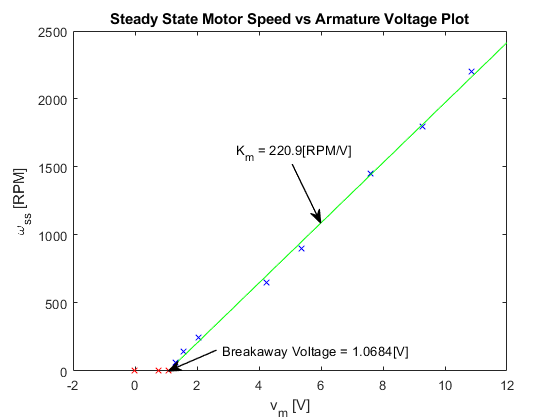


figure
plot(SS_w_v_dat.Vm(BA_index),SS_w_v_dat.MotorSpeed(BA_index), 'r x',SS_w_v_dat.Vm(~BA_index),SS_w_v_dat.MotorSpeed(~BA_index), 'b x', [v_ba 12],[0 Km_fit(1)*12 + Km_fit(2)],'g')
xlabel('v_m [V]')
ylabel('\omega_{ss} [RPM]')
title('Steady State Motor Speed vs Armature Voltage Plot')

%Breakaway Location Annotation
ax = gca;
LArr = .1; %Length of Arrow
PhiArr = deg2rad(30);
%Arrow Head
[xh, yh] = ds2nfu(ax,SS_w_v_dat.Vm(length(SS_w_v_dat.Vm(BA_index))), 0);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['Breakaway Voltage = ' num2str(round(v_ba,4)) '[V]'],'FontSize',10,'Linewidth',1)

%Slope Annotation
ax = gca;
LArr = .15; %Length of Arrow
PhiArr = deg2rad(110);
%Arrow Head
[xh, yh] = ds2nfu(ax,6, Km_fit(1)*6 + Km_fit(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['K_m = ' num2str(round(Km_fit(1),1)) '[RPM/V]'],'FontSize',10,'Linewidth',1)

#### Tachometer Constant

A linear curve fit is used to approximate the tachometer measurement constant $K_t = \frac{v_t}{\omega}$  from experimental data. 

Kt_fit = polyfit(SS_w_v_dat.MotorSpeed,SS_w_v_dat.Vt,1);
fprintf(['Kt is found to be ' num2str(round(Kt_fit(1),3)) ' [V/RPM]'])

Kt is found to be -0.015 [V/RPM]

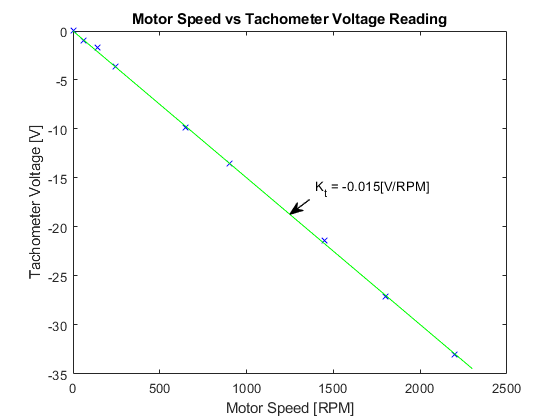


figure
plot(SS_w_v_dat.MotorSpeed,SS_w_v_dat.Vt, 'b x',[0 2300],[0 Kt_fit(1)*2300 + Kt_fit(2)],'g' )
xlabel('Motor Speed [RPM]')
ylabel('Tachometer Voltage [V]')
title('Motor Speed vs Tachometer Voltage Reading')

%Slope Annotation
ax = gca;
LArr = .05; %Length of Arrow
PhiArr = deg2rad(45);
%Arrow Head
[xh, yh] = ds2nfu(ax,1250, Kt_fit(1)*1250 + Kt_fit(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['K_t = ' num2str(round(Kt_fit(1),3)) '[V/RPM]'],'FontSize',10,'Linewidth',1)

#### Inverting Power Amplifier Constant

A linear curve fit is used to approximate the tachometer measurement constant $K_a = ~\frac{v_m}{v_o}$  from experimental data. 

Ka_fit = polyfit(SS_w_v_dat.Vo,SS_w_v_dat.Vm,1);
fprintf(['Ka is found to be ' num2str(Ka_fit(1)) ' [V/V]'])

Ka is found to be -5.0204 [V/V]

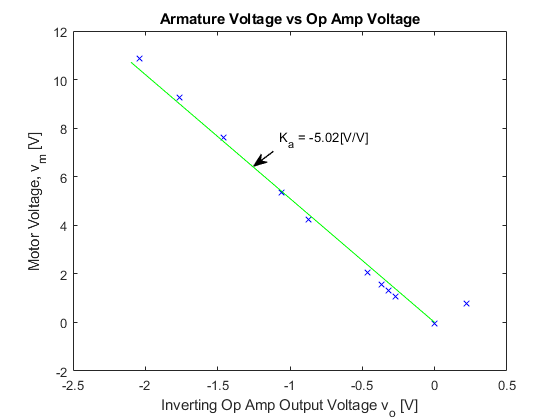

figure
plot(SS_w_v_dat.Vo,SS_w_v_dat.Vm, 'b x',[0 -2.1],[0 Ka_fit(1)*-2.1 + Ka_fit(2)],'g' )
xlabel('Inverting Op Amp Output Voltage v_o [V]')
ylabel('Motor Voltage, v_m [V]')
title('Armature Voltage vs Op Amp Voltage')

%Slope Annotation
ax = gca;
LArr = .05; %Length of Arrow
PhiArr = deg2rad(45);
%Arrow Head
[xh, yh] = ds2nfu(ax,-1.25, Ka_fit(1)*-1.25 + Ka_fit(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['K_a = ' num2str(round(Ka_fit(1),3)) '[V/V]'],'FontSize',10,'Linewidth',1)

#### Potentiometer Constant

Data is separated (roughly) by linear regions of the sawtooth wave and a linear curve fit is given to each. The slopes are then averaged to determine a value in volts per second.

I_p_1 = ((.15 < PositionSensor(:,1)) & (PositionSensor(:,1) < .55));
I_p_2 = ((.63 < PositionSensor(:,1)) & (PositionSensor(:,1) < 1.1));
I_p_3 = ((1.25 < PositionSensor(:,1)) & (PositionSensor(:,1) < 1.75));

m_fit1 = polyfit(PositionSensor(I_p_1,1),PositionSensor(I_p_1,3),1);
fprintf(['First slope fit is ' num2str(m_fit1(1)) ' [V/s]'])

First slope fit is 52.207 [V/s]


m_fit2 = polyfit(PositionSensor(I_p_2,1),PositionSensor(I_p_2,3),1);
fprintf(['Second slope fit is ' num2str(m_fit2(1)) ' [V/s]'])

Second slope fit is 52.496 [V/s]


m_fit3 = polyfit(PositionSensor(I_p_3,1),PositionSensor(I_p_3,3),1);
fprintf(['Third slope fit is ' num2str(m_fit3(1)) ' [V/s]'])

Third slope fit is 52.6473 [V/s]

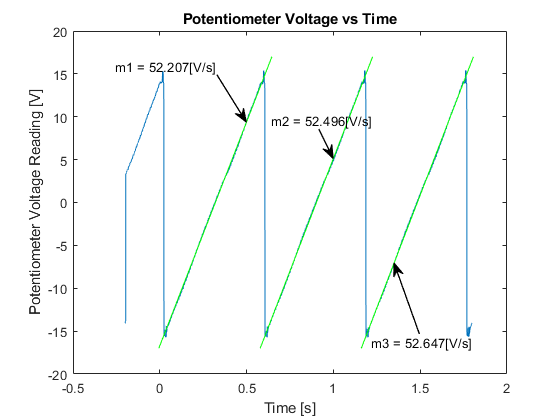


figure
plot(PositionSensor(:,1),PositionSensor(:,3),'-',[(-17 - m_fit1(2))/m_fit1(1)  (17 - m_fit1(2))/m_fit1(1)],[-17 17],'g',...
    [(-17 - m_fit2(2))/m_fit2(1)  (17 - m_fit2(2))/m_fit2(1)],[-17 17],'g' ,[(-17 - m_fit3(2))/m_fit3(1)  (17 - m_fit3(2))/m_fit3(1)],[-17 17],'g'  )
xlabel('Time [s]')
ylabel('Potentiometer Voltage Reading [V]')
title('Potentiometer Voltage vs Time')

%Slope Annotations
ax = gca;

% m_fit1
LArr = .125; %Length of Arrow
PhiArr = deg2rad(115);
%Arrow Head
[xh, yh] = ds2nfu(ax,.5, m_fit1(1)*.5 + m_fit1(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['m1 = ' num2str(round(m_fit1(1),3)) '[V/s]'],'FontSize',10,'Linewidth',1)

% m_fit2
LArr = .075; %Length of Arrow
PhiArr = deg2rad(110);
%Arrow Head
[xh, yh] = ds2nfu(ax,1, m_fit2(1)*1 + m_fit2(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['m2 = ' num2str(round(m_fit2(1),3)) '[V/s]'],'FontSize',10,'Linewidth',1)

% m_fit3
LArr = .175; %Length of Arrow
PhiArr = deg2rad(-75);
%Arrow Head
[xh, yh] = ds2nfu(ax,1.35, m_fit3(1)*1.35 + m_fit3(2));
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['m3 = ' num2str(round(m_fit3(1),3)) '[V/s]'],'FontSize',10,'Linewidth',1)

The period of the sawtooth waveform is found by manually finding the timespan associated with the initial and final positive peak of the data and dividing that by three.


$$T_p = \frac{t_{peak3} - t_{peak0}}{3}$$


Using the average of the slopes determined from the three linear curve fits above, $K_p$ is computed.


$$K_p = \frac{2\pi *avg(m_{fit1},~m_{fit2},~m_{fit3})}{T_p}$$


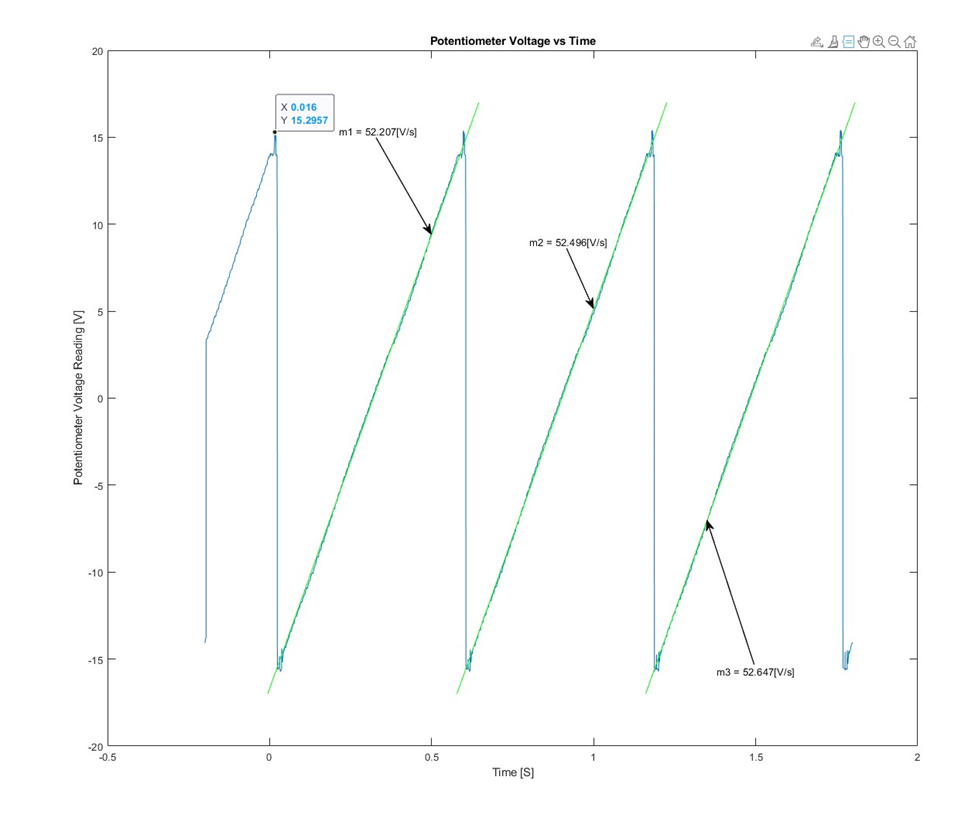

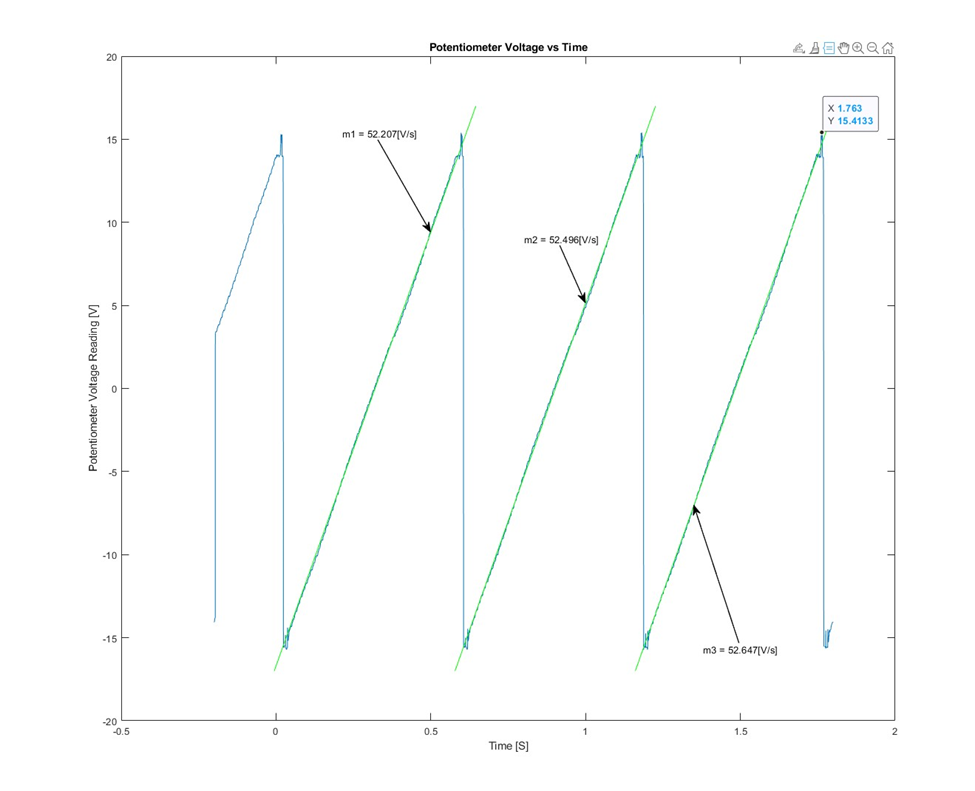

period_st_wave = (1.763 - 0.016)/3;
fprintf(['T_p is found to be ' num2str(round(period_st_wave,3)) ' [sec]'])

T_p is found to be 0.582 [sec]


Kp = -mean([m_fit1(1) m_fit2(1) m_fit3(1)])*period_st_wave/(2*pi);
fprintf(['K_p is found to be ' num2str(round(Kp,1)) ' [V/rad]'])

K_p is found to be -4.9 [V/rad]

The $K_p$ value is slightly less than the expected value of 30 one gets from visually inspecting the data. This is because there is a deadzone nonlinearity present in the potentiometer that occurs right around the rollover point. 

#### Motor Time Constant

First, an estimate of the steady state voltage is found by averaging a range of values near the end of the data collected for each step response. The final one percent of the data points are used for each calculation. 

Index_i_1 = length(Step1(:,1)) - round(length(Step1(:,1))/100);
v_ss_1 = mean(Step1(Index_i_1:end,3));
fprintf(['Steady state tachometer reading 1 is found to be ' num2str(round(v_ss_1,3)) ' [Volts]'])

Steady state tachometer reading 1 is found to be 23.364 [Volts]

Index_i_2 = length(Step2(:,1)) - round(length(Step2(:,1))/100);
v_ss_2 = mean(Step2(Index_i_2:end,3));
fprintf(['Steady state tachometer reading 2 is found to be ' num2str(round(v_ss_2,3)) ' [Volts]'])

Steady state tachometer reading 2 is found to be 25.031 [Volts]

Index_i_3 = length(Step3(:,1)) - round(length(Step3(:,1))/100);
v_ss_3 = mean(Step3(Index_i_3:end,3));
fprintf(['Steady state tachometer reading 3 is found to be ' num2str(round(v_ss_3,3)) ' [Volts]'])

Steady state tachometer reading 3 is found to be 14.092 [Volts]

To better estimate the time constant, a 100 point moving mean is used to attempt to smooth out the data in the transient regions. This is shown in red and overlays the raw data plotted below. 

k = 100;
%Step response 1 smoothed
Step1_movmean = movmean(Step1(:,3),k);
t_Step1_movmean = linspace(Step1(1,1), Step1(end,1), length(Step1(:,1))).';
%Step response 2 smoothed
Step2_movmean = movmean(Step2(:,3),k);
t_Step2_movmean = linspace(Step2(1,1), Step2(end,1), length(Step2(:,1))).';
%Step response 3 smoothed
Step3_movmean = movmean(Step3(:,3),k);
t_Step3_movmean = linspace(Step3(1,1), Step3(end,1), length(Step3(:,1))).';

Next, the first voltage to exceed 63.21% of the step response's steady state voltage is found from the *averaged *data, not the raw data. Its associated time is taken to be the time constant for the response.

mask_tau1 = Step1_movmean <= v_ss_1*.6321;
[v_tau1, I_tau1] = max(Step1(mask_tau1,3));
tau1 = Step1(I_tau1,1);
fprintf(['Time constant for step response 1 is found to be ' num2str(tau1) ' [s]'])

Time constant for step response 1 is found to be 0.28634 [s]


mask_tau2 = Step2_movmean <= v_ss_2*.6321;
[v_tau2, I_tau2] = max(Step2(mask_tau2,3));
tau2 = Step2(I_tau2,1);
fprintf(['Time constant for step response 2 is found to be ' num2str(tau2) ' [s]'])

Time constant for step response 2 is found to be 0.27293 [s]


mask_tau3 = Step3_movmean <= v_ss_3*.6321;
[v_tau3, I_tau3] = max(Step3(mask_tau3,3));
tau3 = Step3(I_tau3,1);
fprintf(['Time constant for step response 3 is found to be ' num2str(tau3) ' [s]'])

Time constant for step response 3 is found to be 0.25984 [s]

Finally, the motor's time constant is taken to be the average of these three values

tau = mean([tau1 tau2 tau3]);
fprintf(['The motor time constant is found to be ' num2str(round(tau,3)) ' [s]'])

The motor time constant is found to be 0.273 [s]

Finally, results are plotted with raw data, smoothed data, steady state voltage value, and associated time constants overlayed. 

**Plot of Step Response 1:**

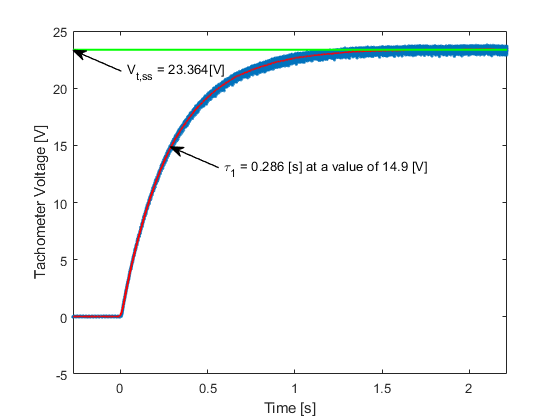

figure
plot(Step1(:,1), Step1(:,3), '.',t_Step1_movmean,Step1_movmean, 'r', [min(Step1(:,1)) max(Step1(:,1))],[v_ss_1 v_ss_1], 'g', 'LineWidth', 1.5)
xlabel('Time [s]')
ylabel('Tachometer Voltage [V]')
xlim([min(Step1(:,1)) max(Step1(:,1))])

%Annotations
ax = gca;

% Steady State Voltage 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax,min(Step1(:,1)), v_ss_1);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['V_{t,ss} = ' num2str(round(v_ss_1,3)) '[V]'],'FontSize',10,'Linewidth',1)

% Time constant 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax, tau1,v_tau1);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['\tau_1 = ' num2str(round(tau1,3)) ' [s] at a value of ' num2str(round(v_tau1, 1)) ' [V]'],'FontSize',10,'Linewidth',1)

**Plot of Step Response 2:**

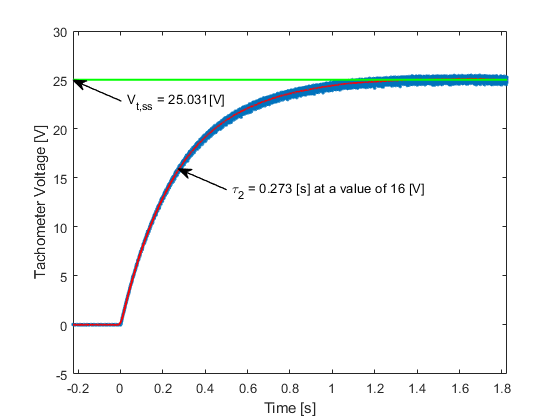

figure
plot(Step2(:,1), Step2(:,3), '.',t_Step2_movmean,Step2_movmean, 'r', [min(Step2(:,1)) max(Step2(:,1))],[v_ss_2 v_ss_2], 'g', 'LineWidth', 1.5)
xlabel('Time [s]')
ylabel('Tachometer Voltage [V]')
xlim([min(Step2(:,1)) max(Step2(:,1))])

%Annotations
ax = gca;

% Steady State Voltage 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax,min(Step2(:,1)), v_ss_2);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['V_{t,ss} = ' num2str(round(v_ss_2,3)) '[V]'],'FontSize',10,'Linewidth',1)

% Time constant 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax, tau2,v_tau2);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['\tau_2 = ' num2str(round(tau2,3)) ' [s] at a value of ' num2str(round(v_tau2, 1)) ' [V]'],'FontSize',10,'Linewidth',1)

**Plot of Step Response 3:**

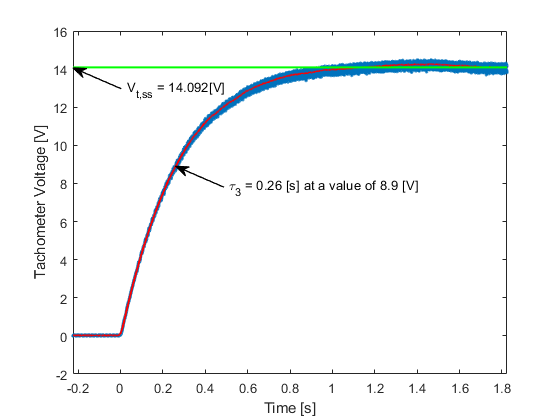

figure
plot(Step3(:,1), Step3(:,3), '.',t_Step3_movmean,Step3_movmean, 'r', [min(Step3(:,1)) max(Step3(:,1))],[v_ss_3 v_ss_3], 'g', 'LineWidth', 1.5)
xlabel('Time [s]')
ylabel('Tachometer Voltage [V]')
xlim([min(Step3(:,1)) max(Step3(:,1))])

%Annotations
ax = gca;

% Steady State Voltage 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax,min(Step3(:,1)), v_ss_3);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['V_{t,ss} = ' num2str(round(v_ss_3,3)) '[V]'],'FontSize',10,'Linewidth',1)

% Time constant 
LArr = .1; %Length of Arrow
PhiArr = deg2rad(-30);
%Arrow Head
[xh, yh] = ds2nfu(ax, tau3,v_tau3);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['\tau_3 = ' num2str(round(tau3,3)) ' [s] at a value of ' num2str(round(v_tau3, 1)) ' [V]'],'FontSize',10,'Linewidth',1)

#### Static Torque Voltage Constant $\frac{K_c}{R_a}$


$$ \frac{K_c}{R_a}~ =~ \frac{MgL}{v_{m,0}}$$


Where


$$M = 0.028~ [kg]$$



$$L = 0.0254~[m]$$



$$g = 9.81 ~[\frac{m}{s^2}]$$



$$v_{m,0} = 0.66~[V]$$


M_n = 28e-3; %[kg]
L_n = 11*.0254; %[m]
g_n = 9.81; %[m/s^2]
vm0 = 0.66; %[V]

KcRa = M_n*g_n*L_n/vm0;
fprintf(['The static torque voltage constant is found to be ' num2str(round(KcRa,4)) ' [Nm/V]'])

The static torque voltage constant is found to be 0.1163 [Nm/V]

#### Torque Required to Break Through the Static Friction in the Step Responses

The motor circuit is modelled in the following manner.

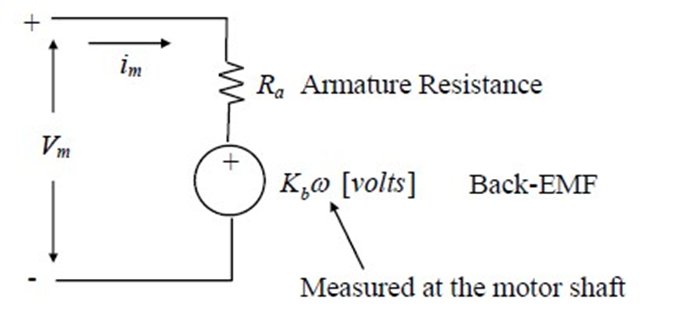

In the static friction case, when the motor is stalled, no $\omega$ has developed in the system and all the electrical power is being dissipated as heat through $R_a$. The armature KVL in this scenario is simply


$$v_m = i_mR_a$$


The torque produced by a DC motor is given by 


$$T_m = K_ci_m$$


Therefore, 


$$T_m ~=~ \frac{K_c}{R_a}v_m$$


The torque required to break the system out stall, $T_{ba}$, is related to the breakaway voltage, $v_{ba}$, from the $\omega_{ss}$ vs $v_a$ dataset through the stalled motor condition. At the tipping point


$$T_{ba} ~=~ \frac{K_c}{R_a}v_{ba}$$


There is an inherent assumption here that most of the static friction torque is lumped at the motor side of the speed reducer, not the pendulum side. In reality, there is a contribution to stiction from the individual mechanical elements of the reducer. Since it would be out of the scope of this report to determine what exactly is contributing to stiction and its consequence on the static force balance problem, this is an assumption that must be made. 

T_ba = KcRa*v_ba;
fprintf(['The breakaway torque is found to be ' num2str(round(T_ba,4)) ' [Nm]'])

The breakaway torque is found to be 0.1242 [Nm]

#### Algebraically Determining the Remaining System Parameters 

First, convert constants to SI units

Km = Km_fit(1)*2*pi/60; %[(rad/s)/V]
fprintf(['The motor velocity constant Km is ' num2str(round(Km,3)) ' [rad/Vs]'])

The motor velocity constant Km is 23.133 [rad/Vs]

Kt = Kt_fit(1)*60/(2*pi); %[V/(rad/s)]
fprintf(['The tachometer constant Kt is ' num2str(round(Kt,3)) ' [Vs/rad]'])

The tachometer constant Kt is -0.143 [Vs/rad]

The friction constant $K_{fm}$ and back emf constant $K_b$ are common to both $\tau_m$ and $K_m$ and can be eliminated. This allows us to solve for the motor inertia in terms of other known constants.


$$J_m ~=~\frac{K_c}{R_a}\frac{\tau_m}{K_m}$$


Jm = KcRa*tau/Km;
fprintf(['The motor polor moment of inertia Jm is ' num2str(round(Jm,4)) ' [kg-m-s^2]'])

The motor polor moment of inertia Jm is 0.0014 [kg-m-s^2]

### Relating Found System Parameters to a Nonlinear Motorized Pendulum Model

A schematic representation of the motorized pendulum system is shown below. 

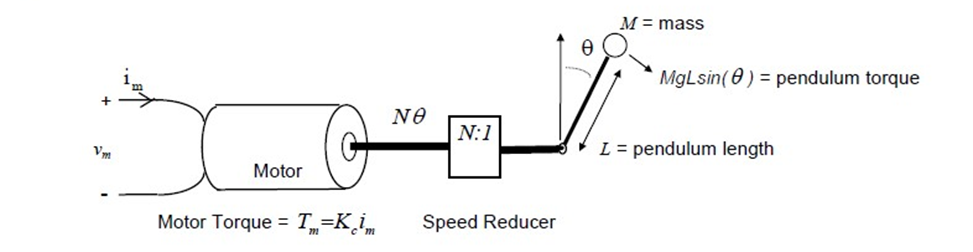

A nonlinear model of the pendulum kinetics is expressed in terms of an input armature voltage actuation as such:

syms K_c R_a v_m N J_m J_p theta_ddot K_fm K_b theta_dot M g L theta K_m


$$\frac{K_c }{R_a } \,v_m~=~\theta^˙ \,{\left(K_{\textrm{fm}} \,N+\frac{K_b \,K_c \,N}{R_a }\right)}+\theta^¨ \,{\left(J_m \,N+J_p \right)}-L\,M\,g\,\mathrm{sin}\left(\theta \right)$$


Where friction due to the pendulum itself is assumed to be negligible. The pendulum's moment of inertia, $J_p$, is given by


$$J_p ~=~ L^2M$$


Jp = L_n^2*M_n;

and $N = 8.1$ is a gear ratio between the motor shaft and the pendulum. The input to the system is voltage $v_m$, the motor's armature voltage - this can be related to our control actuation $v_o$ through $K_a$. This will have to be done for all of the measured states as well so that gain selecting resistors can be placed in the physical electronics. From rearranging the equation for $\tau_m$, the terms $K_{fm} + K_b\frac{K_c}{R_a}$ in the pendulum model can be eliminated in favor of known values. 


$$\tau_m ~=~ \frac{J_m}{K_{fm} + \frac{K_c}{R_a}K_b}$$



$$\frac{\tau_m}{J_m} ~=~ \frac{1}{K_{fm} + \frac{K_c}{R_a}K_b}$$



$$K_{fm} + K_b\frac{K_c}{R_a} ~=~ \frac{J_m}{\tau_m}$$


And from $J_m$ above


$$K_{fm} + K_b\frac{K_c}{R_a} ~=~ \frac{1}{K_m}\frac{K_c}{R_a}$$


Hence

PendulumEOM = K_c/R_a*v_m == (N*J_m + J_p)*theta_ddot + N*1/K_m*K_c/R_a*theta_dot - M*g*L*sin(theta);


$$\frac{K_c \,v_m }{R_a }~=~\theta^¨ \,{\left(J_m \,N+J_p \right)}-L\,M\,g\,\mathrm{sin}\left(\theta \right)+\frac{K_c \,N\,\theta^˙ }{K_m \,R_a }$$


The above model excludes any modelling of additional nonlinearities in the system. The model will be suplemented with a coulomb friction with damping nonlinearity. This replaces the $\frac{K_c \,N\, }{K_m \,R_a }$ damping coefficient in the above model. This damping coefficient is captured by the nonlinear friction model in the slope of the linear regions of the $T_f$ vs $\dot\theta$ plot below. Its offset is the breakaway torque required to overcome the stiction. The signum function inherent in this model will act as a switching law around zero pendulum/motor velocity that tends the system back to zero velocity if the net torques on the armature to not exceed a threshold. 

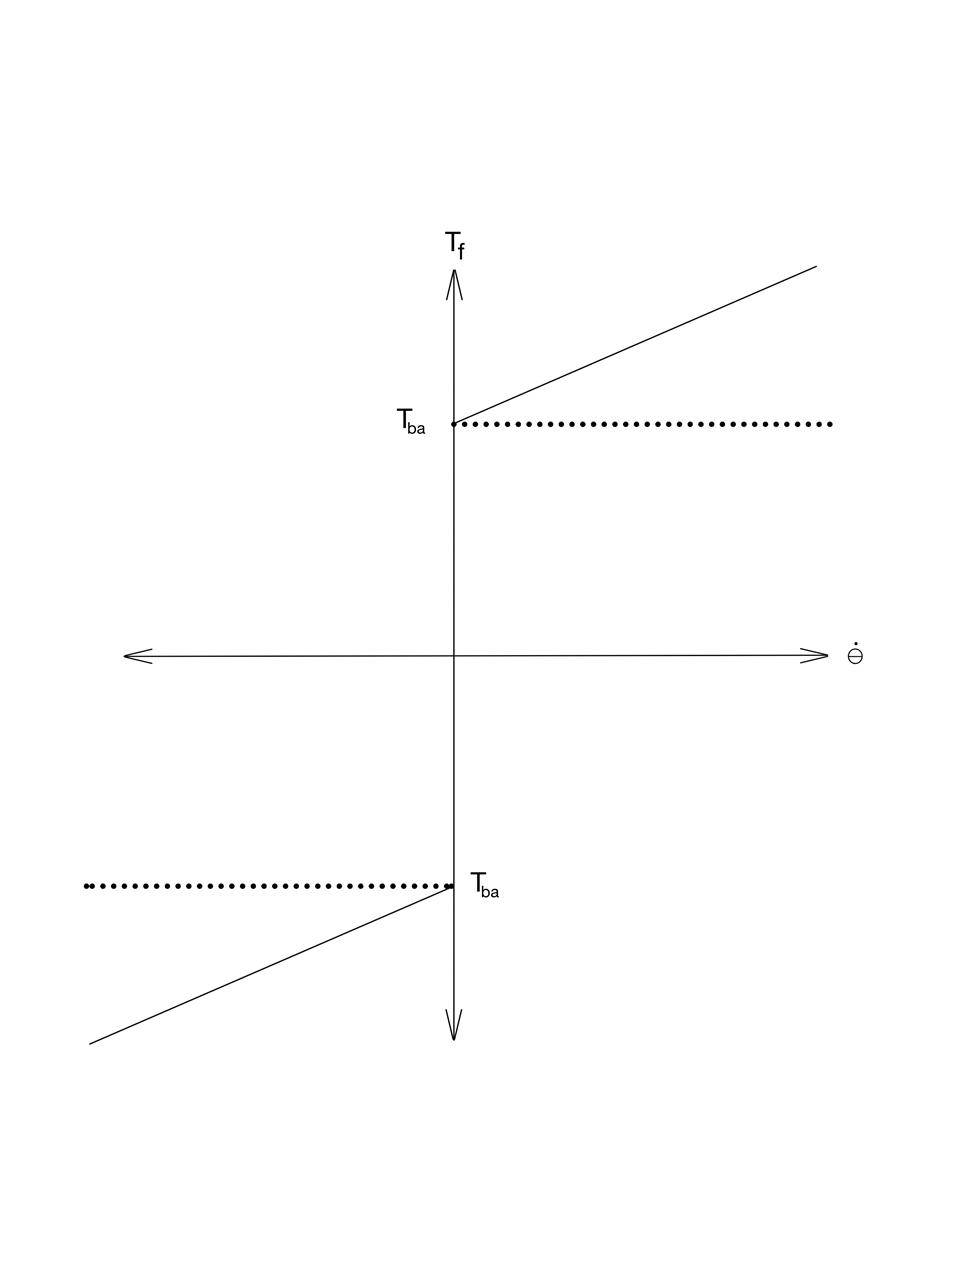

The analytical expression for the friction term $T_f$ is


$$T_f ~=~ |T_{ba}| sign(\dot\theta)~+~  \frac{K_c \,N\, }{K_m \,R_a }\dot\theta$$


and the model pendulom EOM becomes 


$$\frac{K_c \,v_m }{R_a }~=~\theta^¨ \,{\left(J_m \,N+J_p \right)}-L\,M\,g\,\mathrm{sin}\left(\theta \right)-|T_{ba}| sign(\dot\theta)~-~  \frac{K_c \,N\, }{K_m \,R_a }\dot\theta$$


### Nonlinear State Space Representation of the Motorized Pendulum

The nonlinear state space representation *excluding the stiction nonlinearity* is


$$ \dot\overset{\rightharpoonup}{x} ~=~ f(\overset{\rightharpoonup}{x},v_m) $$


where $\overset{\rightharpoonup}{x} ~=~ [\theta~\dot{\theta}]^T$. Hence,

NL_PendulumSS = [theta_dot;theta_ddot] == expand([theta_dot;rhs(isolate(PendulumEOM, theta_ddot))]);


$$

\left\lbrack \begin{array}{c}

\theta^˙\\
\theta^¨ 

\end{array}\right\rbrack 

=

\left\lbrack \begin{array}{c}

\theta^˙\\

\frac{K_c \,v_m }{J_m \,N\,R_a +J_p \,R_a }-\frac{K_c \,N\,\theta^˙ }{J_m \,K_m \,N\,R_a +J_p \,K_m \,R_a }+\frac{L\,M\,g\,\mathrm{sin}\left(\theta \right)}{J_m \,N+J_p }

\end{array}\right\rbrack$$


Taking the Jacobian with respect to the state yields

Jacobian(theta) = jacobian(rhs(NL_PendulumSS), [theta theta_dot]);


$$J_x(\overset{\rightharpoonup}{x}, v_m) ~=~

\left\lbrack \begin{array}{cc}
0 & 1\\
\frac{L\,M\,g\,\mathrm{cos}\left(\theta \right)}{J_m \,N+J_p } & -\frac{K_c \,N}{J_m \,K_m \,N\,R_a +J_p \,K_m \,R_a }
\end{array}\right\rbrack$$


and the Jacobian with respect to the input is simply a linear input matrix B

B = equationsToMatrix(rhs(NL_PendulumSS), v_m);


$$J_u ~=~ B ~=~

\left\lbrack \begin{array}{c}
0\\
\frac{K_c }{J_m \,N\,R_a +J_p \,R_a }
\end{array}\right\rbrack$$


## Stability Analysis

It is clear from the $f(\overset{\rightharpoonup}{x},v_m)$ that the open loop ($v_m ~=~0$) equilibrium points are located at $\dot{\theta} ~=~ 0$, and $\sin(\theta) =~ 0$. So, for $\theta$ at integer multiples of $\pi$, the pendulum is naturally stable when it is still. It is also possible to consider the actuated equilibrium points, ones where $v_m$ is compensating for gravity at an arbitrary pendulum angle. One can imagine designing a feed-forward control law around those points where feed forward voltage $v_{m,ff}$ creates an equilibrium point at $\theta_{eq}$. A regulator around error states in position and velocity can then be analyzed for stability. There are likely many different ways to consider stability in the actuated case, all depending on the control law utilized. This paper will focus on stability analysis of the natural equilibrium points as well as a closed loop stability analysis of the operating point at $\theta=0$. 

The two natural equilibrium points will be analyzed for open loop stability. The upward position, $\theta=0$, will be shown asymptotically unstable using Lyapunov's indirect method. The downward position, $\theta=\pi$, will be shown asymptotically stable using the same method. A stabilizing linear quadratic regulator will be designed about the upward operating point. Again, Lyapunov's indirect method will be used to argue for asymptotic stability of the closed loop system.

### Natural Equilibrium Points

Since $(\theta,\dot{\theta})=(0,0)$ is an equilibrium point, it is valid to use Lyapunov's indirect method to make a statement about the asymptotic stability of the point.  Eigenvalue analysis of the system's Jacobian evaluated at that point tells us if the point is asymptotically stable or unstable. The Jacobian here will be denoted $A_1$

N_n = 8.1; %Gear ratio
NumJacobian(theta) = subs(Jacobian, [L, M, g, J_m, J_p, N, K_m],[L_n, M_n, g_n, Jm, Jp, N_n, Km]);
NumJacobian(theta) = subs(NumJacobian, K_c/R_a,  KcRa);
A1 = NumJacobian(0);
eig(A1);


$$A_1~=~\left\lbrack \begin{array}{cc}
0 & 1\\
5.7692 & -3.0608
\end{array}\right\rbrack$$


The eigenvalues of this matrix are


$$\left\lbrack \begin{array}{c}
\lambda_1\\
\lambda_2
\end{array}\right\rbrack

~=~

\left\lbrack \begin{array}{c}
-4.3784\\
1.3177
\end{array}\right\rbrack$$


Since one of the eigenvalues is positive real, the point is asymptotically unstable. 

The point $(\theta,\dot{\theta})=(\pi,0)$ is also an equilibrium point. Its Jacobian is $A_2$

A2 = NumJacobian(pi);
eig(A2);


$$A_2 ~=~ \left\lbrack \begin{array}{cc}
0 & 1\\
-5.7692 & -3.0608
\end{array}\right\rbrack$$


The eigenvalues of this matrix are


$$\left\lbrack \begin{array}{c}
\lambda_1\\
\lambda_2
\end{array}\right\rbrack

~=~

\left\lbrack \begin{array}{c}
-1.5304-1.8513\,\mathrm{i}\\
-1.5304+1.8513\,\mathrm{i}
\end{array}\right\rbrack$$


Since neither of these have a positive real part, the point is asymptotically stable. 

### Stability of a Linear Quadratic Regulator about Upward Position

For an actuated system, the linearization necessary for Lyapunov's indirect method must include a nominal value of the actuation. 


$$f(\overset{\rightharpoonup}{x},v_m) 
 ~\approx~ 
f(\overset{\rightharpoonup}{x_0},v_{m,0})  
+ J_x(\overset{\rightharpoonup}{x_0},v_{m,0})\delta\overset{\rightharpoonup}{x_0} + J_u(\overset{\rightharpoonup}{x_0},v_{m,0})\delta v_m$$


Since the system is naturally stable at the operating point, if $v_m ~=~ -K\overset{\rightharpoonup}{x}$ where $K ~=~ [K_1 ~K_2]^T$, then 


$$v_{m,0} ~=~ -K\overset\rightharpoonup{x_0} ~=~ \overset\rightharpoonup{0}$$


and 


$$\delta v_m ~=~ v_m$$


Therefore a full state feedback law in absolute actuation is possible. A change of variables to deviation states will not be necessary to implement the linear controller. The linearized system with full state feedback has the closed loop matrix $A\prime_{1} ~=~A_1 - BK$. If a $K$ matrix is chosen such that the eigenvalues of $A\prime_{1}$ have negative real part, then the equilibrium point will be closed loop asymptotically stable. Since solutions to the linear quadratic regulator problem are guaranteed to produce stable eigenvalues in the closed loop matrix, our system will be asymptotically stable at the upward operating point. This will prove to be insufficient for good control however. It only guarantees that there is *some* region in the state space for which trajectories that begin within that region will asymptotically approach the operating point. If it is desired to obtain information about the size of this region, additional Lyapunov techniques would be necessary. These alternatives will not be explored in this paper. Below is the linearized system for the LQR controller.


$$f(\overset{\rightharpoonup}{x},v_m) 

 ~\approx~ 

J_x(\overset{\rightharpoonup}{0},-K\overset{\rightharpoonup}{0})\overset{\rightharpoonup}{x} 

+ J_u(\overset{\rightharpoonup}{0},-K\overset{\rightharpoonup}{0})(-K\overset{\rightharpoonup}{x} )$$


i.e.


$$\dot\overset{\rightharpoonup}{x} 

 ~\approx~ 

A_1\overset{\rightharpoonup}{x} 

- BK\overset{\rightharpoonup}{x} $$



$$\dot\overset{\rightharpoonup}{x} 

 ~\approx~ 

(A_1

- BK)\overset{\rightharpoonup}{x} $$



$$\dot\overset{\rightharpoonup}{x} 

 ~\approx~ 

A\prime_{1}\overset{\rightharpoonup}{x} $$


This stability analysis has not taken into account the nonlinear stiction present in the system. This could prove to be a problem for some controllers as high stiction could cause integrator windup, steady state error affecting the asymptotic nature of the equilibrium points, or some other type of effect. This analysis will only consider the stiction through simulation. 

### Simulated Step Responses of the System with Stiction and no Pendulum

This shows that the modelled system, with stiction, reproduces the steady state velocity vs armature voltage relationship - that the $K_m$ and $V_{ba}$ values computed from raw data are represented in the model. Below is a plot of the raw data, original curve fit, and a set of steady state values from simulation step responses. The $K_m$ value was utilized in the model along with the other constants determined above and the stiction nonlinearity. The $K_m$ curve fit and the simulated data line up so perfectly that one set is hidden by the other. This is an indicator that, at the very least, the parameters found from experimental data are consistent with each other and with the model. It also indicates that significant elements of the raw data are represented by the simulation utilized in the control system design. 

u_sel = 1; 
tsim = 4;
r = 15; 
omega_ss = zeros(r,1);
Steps = linspace(v_ba,12,r);
x0 = [0 0];
for i = 1:r
    
    V_step = Steps(i);
    StepOut = sim('Motor_Step_Response');
    omega_ss(i) = StepOut.x(end,2)*60/(2*pi);
    
end


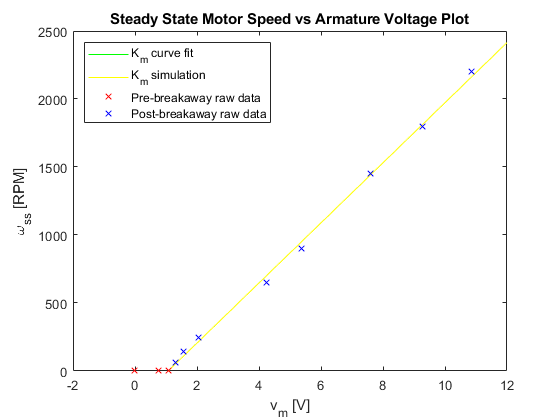

figure
plot([v_ba 12],[0 Km_fit(1)*12 + Km_fit(2)],'g',Steps,omega_ss, 'y',SS_w_v_dat.Vm(BA_index),SS_w_v_dat.MotorSpeed(BA_index), 'r x',SS_w_v_dat.Vm(~BA_index),SS_w_v_dat.MotorSpeed(~BA_index), 'b x'  )
xlabel('v_m [V]')
ylabel('\omega_{ss} [RPM]')
title('Steady State Motor Speed vs Armature Voltage Plot')
legend('K_m curve fit', 'K_m simulation', 'Pre-breakaway raw data', 'Post-breakaway raw data','Location', 'northwest')

To illustrate that the transient response characteristics are captured by the model, the three experimental step responses are simulated and compared to the raw data. 

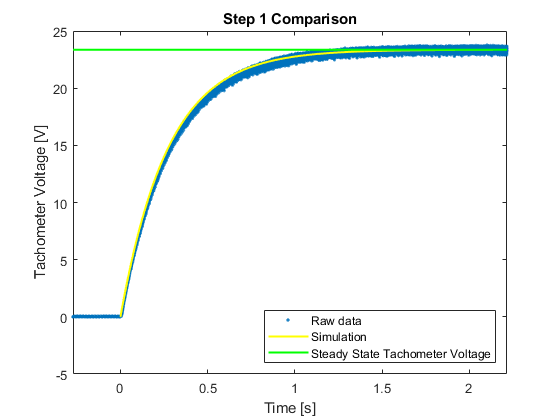

%Simulate step response 1 and plot it alongside its empirical counterpart
V_step = (-v_ss_1/Kt_fit(1) - Km_fit(2))/Km_fit(1); 
Step1_sim = sim('Motor_Step_Response');
omega_step1 = -Kt*Step1_sim.x(:,2);

figure
plot(Step1(:,1), Step1(:,3), '.',Step1_sim.tout,omega_step1, 'y', [min(Step1(:,1)) max(Step1(:,1))],[v_ss_1 v_ss_1], 'g', 'LineWidth', 1.5)
xlabel('Time [s]')
ylabel('Tachometer Voltage [V]')
title('Step 1 Comparison')
xlim([min(Step1(:,1)) max(Step1(:,1))])
legend('Raw data', 'Simulation', 'Steady State Tachometer Voltage','Location', 'southeast')

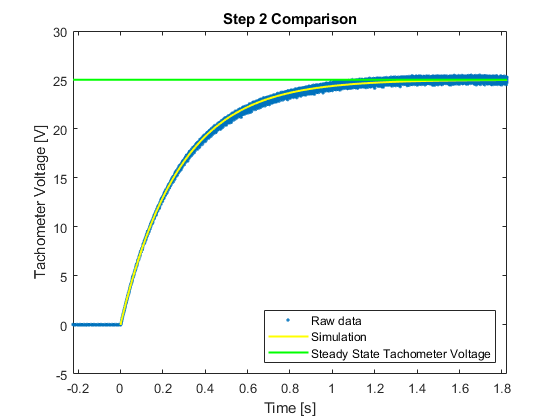


%Simulate step response 2 and plot it alongside its empirical counterpart
V_step = (-v_ss_2/Kt_fit(1) - Km_fit(2))/Km_fit(1); 
Step2_sim  = sim('Motor_Step_Response');
omega_step2 = -Kt*Step2_sim.x(:,2);

figure
plot(Step2(:,1), Step2(:,3), '.',Step2_sim .tout,omega_step2, 'y', [min(Step2(:,1)) max(Step2(:,1))],[v_ss_2 v_ss_2], 'g', 'LineWidth', 1.5)
xlabel('Time [s]')
ylabel('Tachometer Voltage [V]')
title('Step 2 Comparison')
xlim([min(Step2(:,1)) max(Step2(:,1))])
legend('Raw data', 'Simulation','Steady State Tachometer Voltage', 'Location', 'southeast')

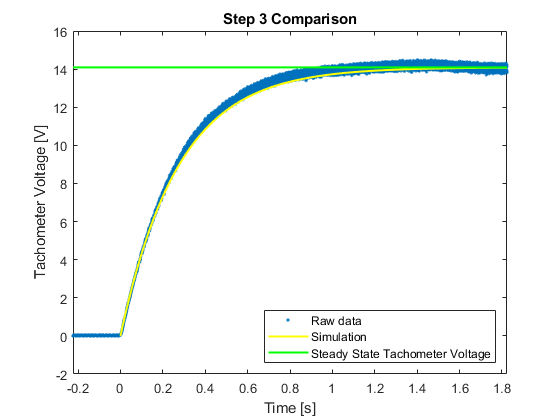


%Simulate step response 3 and plot it alongside its empirical counterpart
V_step = (-v_ss_3/Kt_fit(1) - Km_fit(2))/Km_fit(1); 
Step3_sim  = sim('Motor_Step_Response');
omega_step3 = -Kt*Step3_sim.x(:,2);

figure
plot(Step3(:,1), Step3(:,3), '.',Step3_sim .tout,omega_step3, 'y', [min(Step3(:,1)) max(Step3(:,1))],[v_ss_3 v_ss_3], 'g', 'LineWidth', 1.5)
xlabel('Time [s]')
ylabel('Tachometer Voltage [V]')
title('Step 3 Comparison')
xlim([min(Step3(:,1)) max(Step3(:,1))])
legend('Raw data', 'Simulation','Steady State Tachometer Voltage', 'Location', 'southeast')

All three step responses match up very well with the experimental data. They all lie within the spread of the data and they all approach toward the approximation of the steady state tachometer voltage. It is concluded that the motor modelling is, at least partically, successful. Meaningful conclusions can be drawn from the simulations below, so long as the influence of the pendulum is modelled well enough. 

## Linear Quadratic Regulator Design

The Q and R matrices are initially chosen to give the $\dot\theta$ about a quarter of the weighting of the $\theta$ state. We are saying that we dont care so much if the pendulum moves quickly as the controller regulates it to the upward postion, we care more about the error in postion. The R matrix is given a heavier weighting than either as we are worried about saturating out actuator. We would like to land close to the 15V rails of the inverting power amplifier to allow for timeliness/aggressiveness of the response but we don't want to get too close. 

Since the model is using the small angle approximation, torque required to produce an angular acceleration will be greatly overestimated the larger $\theta$ gets. The nonlinear system is bounded in the gravitational torque that must be countered, but the linear system is not. Since our system starts at $\theta ~=~ 110^^{\circ}$, the gravitational torque is actually closer to the torques estimated by the linear system near the operating point. Any overly aggressive controller will put too much momentum into the pendulum during the early stages of the response and it may not be able to compensate as the pendulum enters the small angle region. To produce a softer response, a large wieght is given to $v_m$.

#### LQR Attempt 1

Initially, weighting matrices are chosen as follows


$$Q ~=~ \left\lbrack \begin{array}{cc}
1 & 0\\
0 & 0.2500
\end{array}\right\rbrack$$



$$R ~=~ 5$$


Q_theta = 1; %weighting on theta state - we DONT want the theta state to move UP initially and we also don't want too much overshoot
Q_thetad = 0.25*Q_theta; %weighting on theta dot state - we dont care as much about how fast the pendulum moves. We prefer lower positional oscillation
Q = [Q_theta 0;0 Q_thetad];

R = 5; %weighting on the voltage actuation - helps us try to avoid input saturation

%Create numerical A1 matrix
A1_n = double(A1);
% Create a numerical B matrix
B = subs(B, [L, M, g, J_m, J_p, N, K_m],[L_n, M_n, g_n, Jm, Jp, N_n, Km]);
B = subs(B, K_c/R_a, KcRa);
B_n = double(B);
%C matrix is the identity
C = eye(2);
%No input to output coupling
D = 0;

%Get K matrix from LQR command
K = lqr(A1_n, B_n, Q,R);

Resulting in a gain matrix 


$$K ~=~ \left\lbrack \begin{array}{cc}
1.4572 & 0.3612
\end{array}\right\rbrack$$


Results of the LQR regulation control scheme produce a slow response and a much softer actuation than allowed by the proposed design criteria.

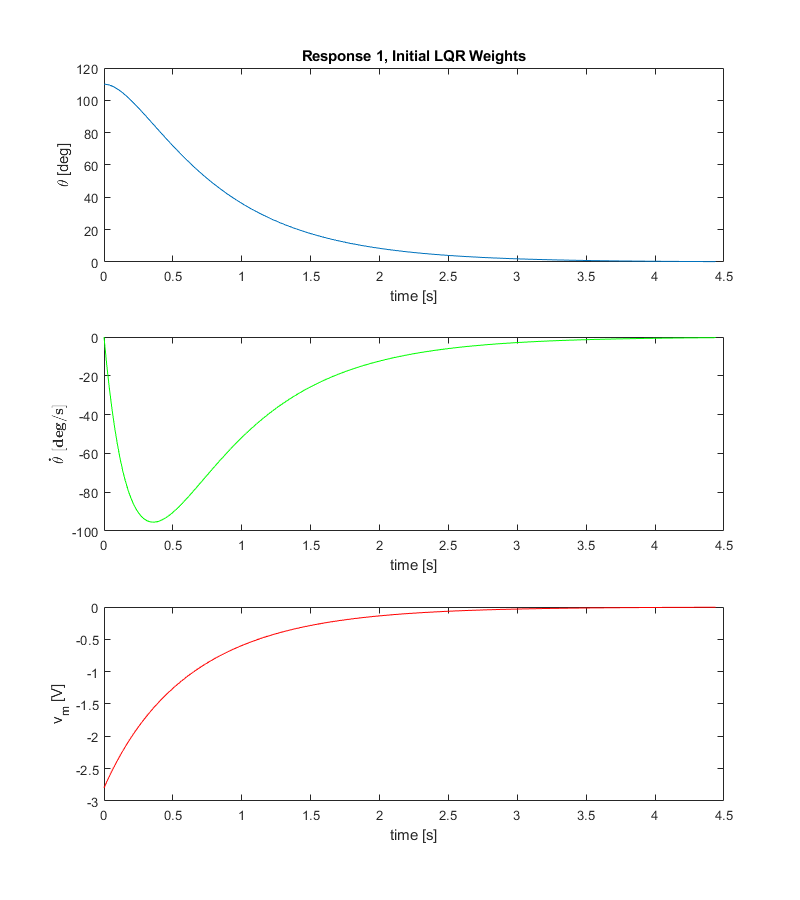

%Create closed loop state space object
SS_model = ss(A1_n - B_n*K,[0;0], C, D); 

%Set initial conditions to zero velocity and theta of 110 degrees
x0 = [deg2rad(110), 0]';

%Run the simulation
[x_lin1, t_lin1] = initial(SS_model, x0);

vm_lin1 = zeros(size(t_lin1));
for i = 1:length(t_lin1)
    
    vm_lin1(i) = -K*x_lin1(i,:)';
    
end

%Plot the results
figure
subplot(3,1,1)
plot(t_lin1,rad2deg(x_lin1(:,1)))
xlabel('time [s]')
ylabel('\theta [deg]')
title('Response 1, Initial LQR Weights')

subplot(3,1,2)
plot(t_lin1,rad2deg(x_lin1(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');


subplot(3,1,3)
plot(t_lin1,vm_lin1, 'r')
xlabel('time [s]')
ylabel('v_m [V]')
set(gcf,'position',[0,0,800,900]);

The  response settles out at about 4 seconds and the maximum actuation is only, roughly -2.75 V. A more aggressive controller will likely be able to make the response much quicker and get closer to the 10V actuation goal. This may be accomplished by lowering the wieght on $v_m$. 

#### LQR Attempt 2

Q is kept at the same values but R is lowered by order of two orders of magnitude.  


$$Q ~=~ \left\lbrack \begin{array}{cc}
1 & 0\\
0 & 0.2500
\end{array}\right\rbrack$$



$$R ~=~ 0.05$$


resulting in 


$$K ~=~\left\lbrack \begin{array}{cc}
5.1806 & 2.1614
\end{array}\right\rbrack$$


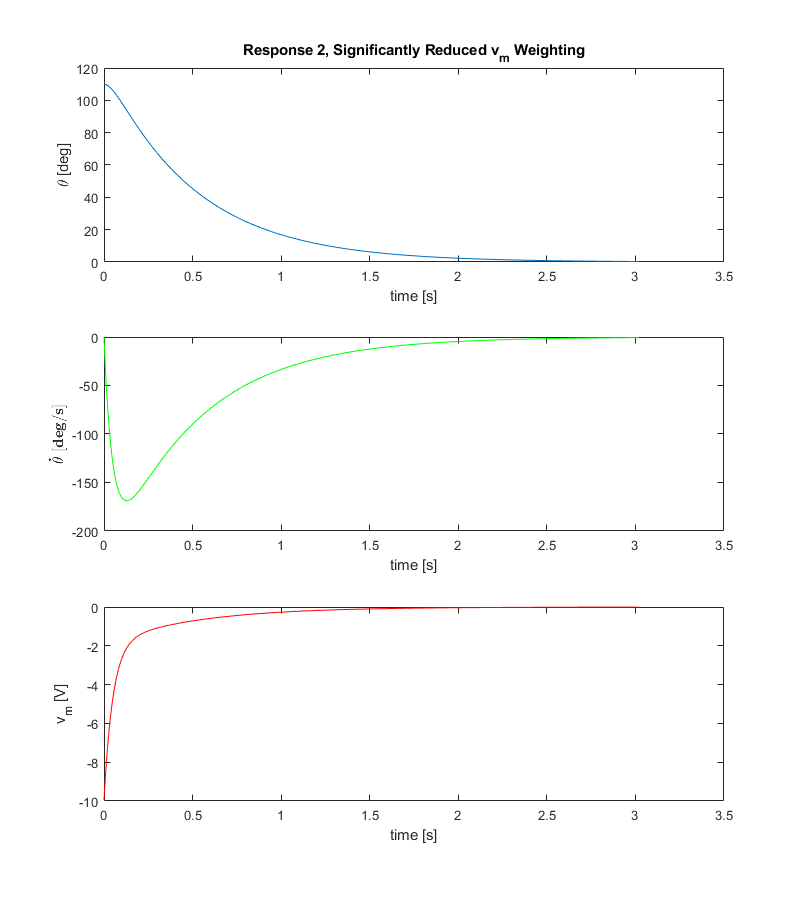

R = .05; %Reduced weight on vm
%Get K matrix from LQR command
K = lqr(A1_n, B_n, Q,R);

%Create closed loop state space object
SS_model = ss(A1_n - B_n*K,[0;0], C, D); 

%Run the simulation
[x_lin1, t_lin1] = initial(SS_model, x0);

vm_lin1 = zeros(size(t_lin1));
for i = 1:length(t_lin1)
    
    vm_lin1(i) = -K*x_lin1(i,:)';
    
end

%Plot the results
figure
subplot(3,1,1)
plot(t_lin1,rad2deg(x_lin1(:,1)))
xlabel('time [s]')
ylabel('\theta [deg]')
title('Response 2, Significantly Reduced v_m Weighting')

subplot(3,1,2)
plot(t_lin1,rad2deg(x_lin1(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');


subplot(3,1,3)
plot(t_lin1,vm_lin1, 'r')
xlabel('time [s]')
ylabel('v_m [V]')
set(gcf,'position',[0,0,800,900]);

It is found that a significantly reduced R value, using the same Q matrix, produces a much more aggressive controller with initial actuation voltage of 10, the design goal. The velocity is quite high and the response is snappier, settling at about 2.5 seconds. This may be fine, it is desired to push hard initially so that the increases torque demand has a chance of being satisfied in the nonlinear system . The resultant velocities, near t = 0, will be much smaller here than in the linear system, but ideally there will be enough upward momentum to carry the pendulum through the regions where the actuation begins to soften. Below, we will see how this controller performs in the nonlinear system with an initial condition that drastically disregards the small angle approximation of the linearization. 

## Simulation of the LQR Controller in the Nonlinear System

The Nonlinear Simulink implementation takes into account the measurement gains, the inverting op amp, and the inverting power amplifier. 

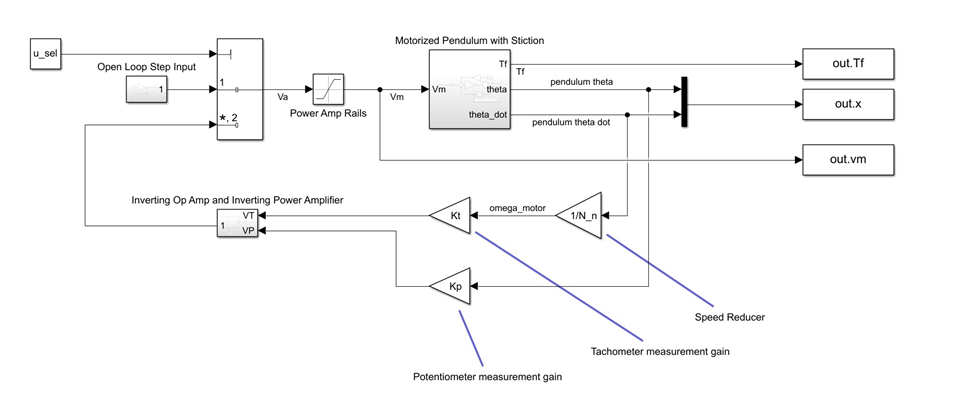

Where the "Motorized Pendulum with Stiction" subsystem contains the equations fo motion in pendulum $\theta$ states

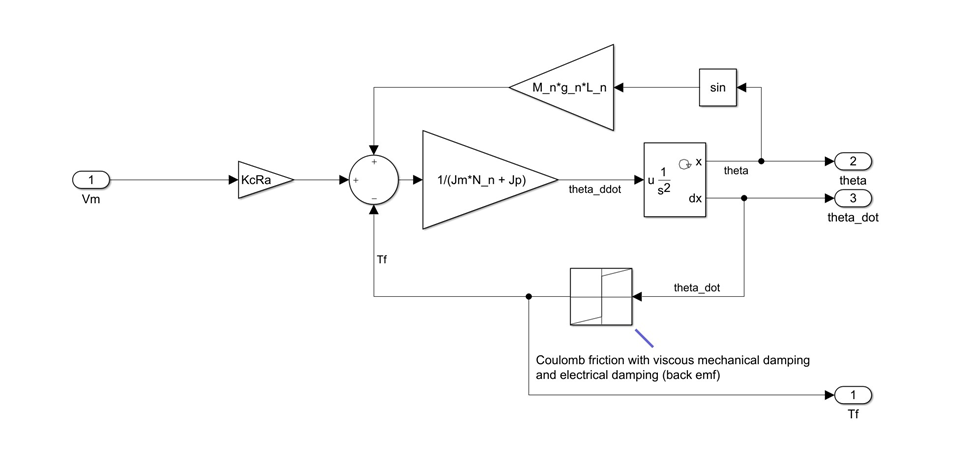

and the "Inverting Op Amp and Inverting Power Amplifier" subsystem contains the op amp gains associated with the physical hardware. The LQR gains must take these into account as well as the measurement gains. 

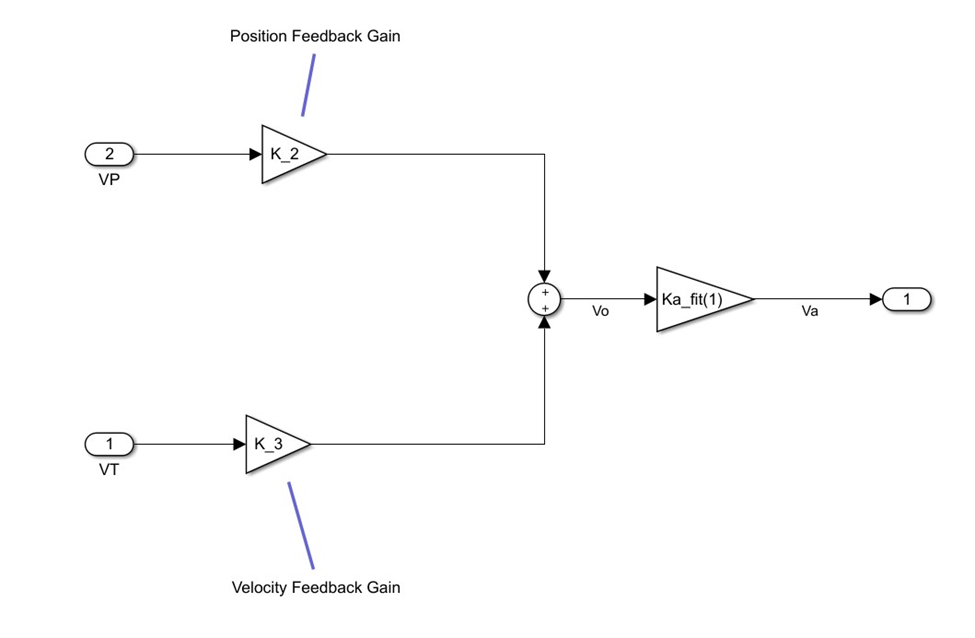

The LQR gains are altered in their sign to account for the inverting nature of the op amp, they are divided by their respective measurement gain, and they are divided by the inverting power amplifier gain. This is all to make the output of the physical hardware the correct scale. 


$$K_2 = -\frac{1}{K_pK_a}[1 ~0]K$$



$$K_3 = -\frac{1}{K_tK_a}[1 ~0]K$$


The nonlinear system with stiction is simulated using the Q and R matrices of LQR try number two above. Results are as follows

u_sel = 2; 
tsim = 1.5;

K_2 = -K(1)/(Kp*Ka_fit(1));
K_3 = -K(2)/(Kt*Ka_fit(1));

NLout = sim('Motorized_Pendulum');

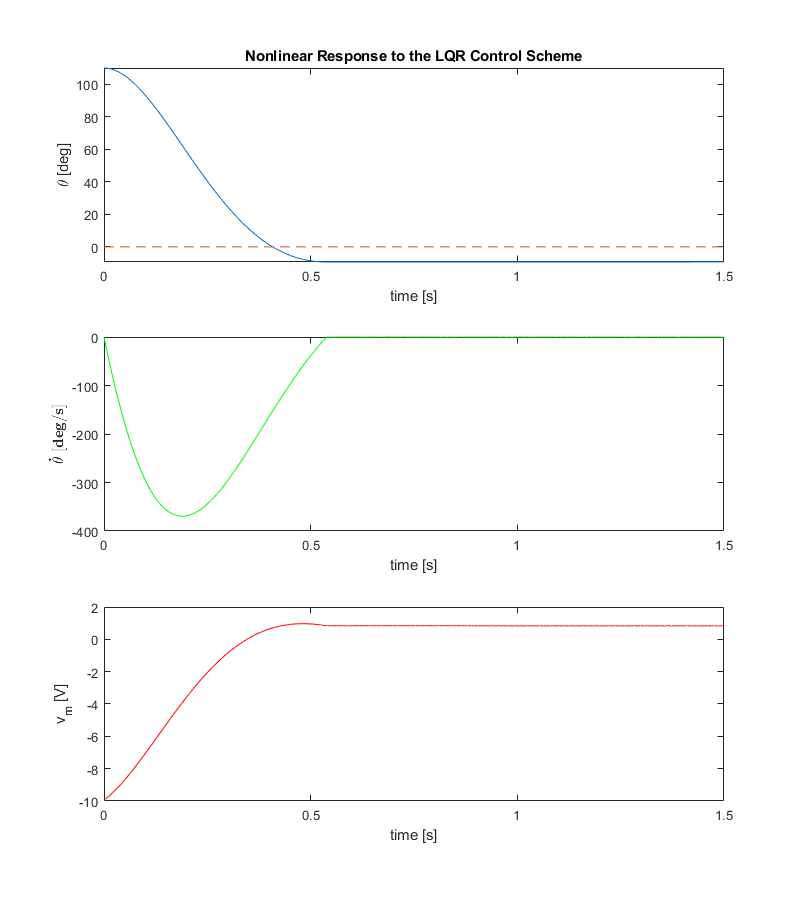


%Plot the results
figure
subplot(3,1,1)
plot(NLout.tout,rad2deg(NLout.x(:,1)), [0 NLout.tout(end)], [0 0], '--' )
xlabel('time [s]')
ylabel('\theta [deg]')
title('Nonlinear Response to the LQR Control Scheme')

subplot(3,1,2)
plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');


subplot(3,1,3)
plot(NLout.tout,NLout.vm, 'r')
xlabel('time [s]')
ylabel('v_m [V]')
set(gcf,'position',[0,0,800,900]);

## Discussion

The nonlinear system response overshoots the equilibrium point and then gets stuck in a region of stiction at about $-9^^{\circ}$. The overshoot occurs because at the initial condition, the moment arm on the gravitational force is much smaller than in the completely horizontal case the 10 V the actuator had been chosen for in the first place. In fact, in this region, the actuator has a similar effect on the system as it does when the pendulum is near the operating point. The linear approximation estimates that the spring force pulling $\theta$ away from zero, when $\theta ~=~ 110^^{\circ}$ is much greater than when it is close. Therefore, the actuation it asks for jolts the pendulum up much faster than is predicted by the linear system The pendulum's momentum causes it to overshoot even after the pendulum enters the small angle region. The higher velocity error is able to push back against the high actuation a bit and reduce its aggressiveness when compared to the linear control actuation, but it is not enough to bring the momentum back down in time. 

One reason the system gets stuck in stiction is that there are no integrators in the system that can ramp up effort as the state remains away from the operating point. A good first step at making the linear controller work better in the presence of stiction would be to add in some integral action. It would have to be a slow integrator so that it doesnt jolt the system through the stiction and become unstable in that manner, bouncing around equilibrium points in the "sticky" system. This would help with the stiction, but it would not make up for the model inaccuracies at such large angular displacements. 

The LQR controller could be tuned to balance the initial jolt the sytem gets by overestimating the actuation necessary to "get the ball rolling" with the need to be able to push through the mostly horizontal stages. But this is attempting to work within a realm that is just not well suited for a linear controller. Also, if the initial conditions were even more severe, or different in some other way, the fine tuning of this particular situation would likely have been in vain. To further motivate the use of a nonlinear controller, this linear control scheme is entirely unsuited to deal with the stiction, and there needs to be some compensation for that in any real implementation. 